% 清除内容
clear all
clc

# task1

灰度图像的字典学习模型及算法

将参考示例代码，将他的功能封装成一个函数，输入灰度图片，和相应的参数，得到它对应的字典D,以及每步的误差有多大

%参数设置
p = [1, 1]* 9; % size of dictionary atoms
nA = prod(p); % number of Atoms
gap = 4; % control the overlapping
lambda = 50; % regularization parameter
tol = 1e-3; 
maxits = 1e3; % maximum number of interation

000500, time: 26.11s, rel_error: 4.29e-04, obj_value: 7.98e+07...


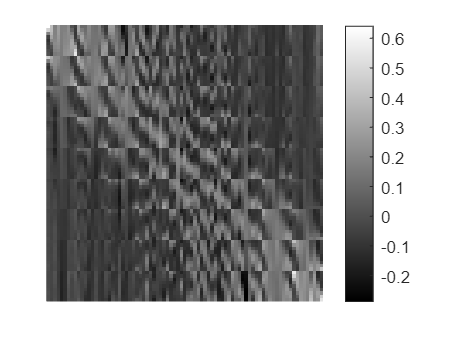

D_barbara =     0.6760    0.4211    0.1223    0.2962    0.1653    0.1954    0.2079    0.0036   -0.0497    0.3080    0.0593    0.0925    0.2093    0.1268    0.1112    0.1784    0.0045   -0.0598    0.2862    0.2937    0.0591    0.0017   -0.2441   -0.1165    0.1272    0.0395   -0.0233    0.1236    0.0281   -0.2138   -0.0554    0.0491    0.1599   -0.0875   -0.0620   -0.1280    0.1635    0.0368   -0.1382   -0.1557    0.0306    0.1139   -0.1785   -0.0685   -0.0274    0.1480    0.0368   -0.0386   -0.0833    0.0788
    0.4476    0.4115    0.1225    0.2960    0.1657    0.1961    0.2145    0.0744   -0.0723    0.3214    0.1361    0.0956    0.2057    0.1289    0.1186    0.1711    0.0396   -0.0745    0.2668    0.2676    0.0907    0.0194   -0.2473   -0.1354    0.1135    0.1534   -0.0351    0.1489    0.0510   -0.2359   -0.0820    0.0578    0.1771   -0.1067   -0.0773   -0.1340    0.1560    0.0319   -0.1248   -0.0328    0.0476    0.0913   -0.1066   -0.0733   -0.0569    0.1274   -0.0751   -0.0623    0.0

ek =          0
    0.6365
    0.2394
    0.2571
    0.1112
    0.0739
    0.0611
    0.0492
    0.0431
    0.0382


[D_barbara, ek_barbara] = gray_image_dictionary('filename','lena_512.png', 'tolerance', tol, 'max_iterations', maxits);      

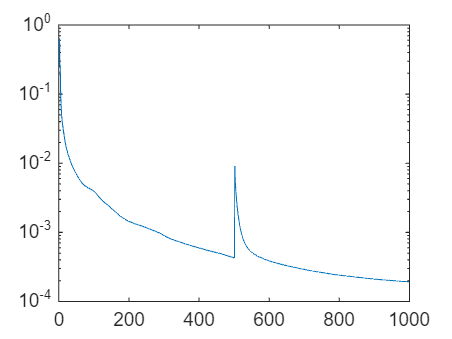

fprintf('\n');
figure(002), clf;
semilogy(ek_barbara);

# Task2

彩色图像的字典学习模型及算法

000500, time: 25.27s, rel_error: 4.36e-04, obj_value: 6.75e+07...


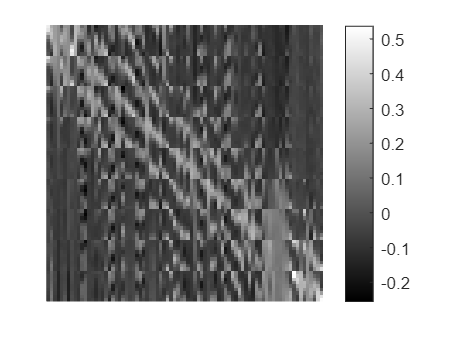

   215   214   214   209   208   210   213   208   210   209



[D_McM12, ek_McM12] = color_image_dictionary('filename','McM12.tif', 'tolerance', tol, 'max_iterations', maxits);

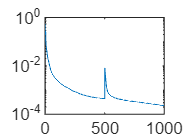

fprintf('\n');
figure(002), clf;
semilogy(ek_McM12);